# Filtering Random Signals and Time Series Data

## 1. Moving Average (MA) Process

For more info on a Moving Average process, look at [Wikipedia](https://en.wikipedia.org/wiki/Moving-average_model). In the following code, we will simulate samples of a process $X,\textrm{MA}\left(2\right)$ with $b_1 =1\ldotp 5,{\;b}_2 =-1\ldotp 2$ and $\sigma^2 =1$. Based on the definition of a Moving Average process, we have:


$$X\left(n\right)=1+\sum_{k=1}^2 b_k \epsilon_{n-k} ,\;\;\;\;\;\;\;\;\epsilon ~N\left(0,1\right)$$


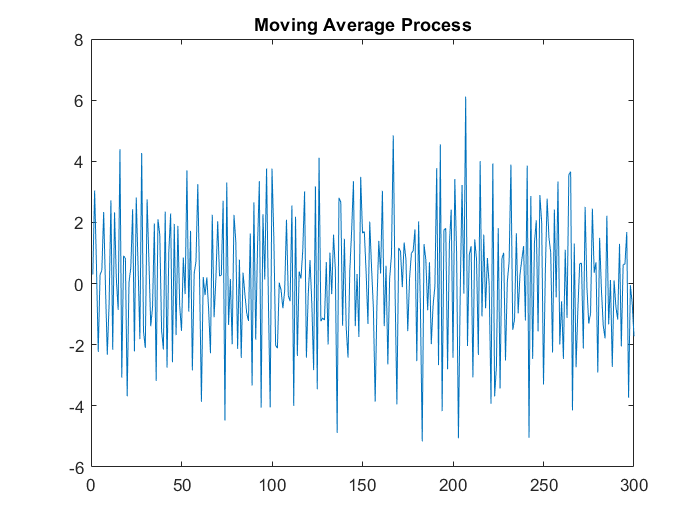

N = 300;
b1 = 1.5;
b2 = -1.2;
sig_carr = 1;
X = zeros(N,1);
e = normrnd(0, sig_carr, 2,1);
b = [b1; b2];

for i=1:N
   e(2) = normrnd(0, sig_carr);
   X(i) = normrnd(0, sig_carr) + fliplr(b)'*e; 
   e(1) = e(2);
end

figure
plot(X)
title('Moving Average Process')

### 2. Processes with limited frequency band

 We will demonstrate a low pass filter $b$ with a cutoff frequency of $f_c /f_s$, where $f_c =1000\;\textrm{Hz}$ and the samling frequency is $f_s =10000\;\textrm{Hz}$. SInce the spectral density of the process is constant, the ${\textrm{TFTD}}^{-1}$ is an impulse at $t=0$, which justifies applying white noise as the input to the filter.

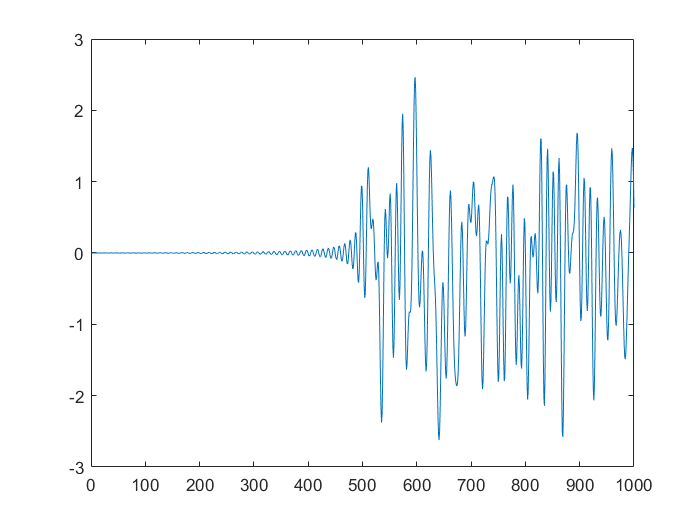

fc = 1000;
N = 1000;
fs = 10000;
P = 2;
b = fir1(N-1,2*fc/fs);
a = 1;
%e = normrnd(0, sqrt(sig_carr), N,1);
e = wgn(N, 1, 20*log10(P));
X=filter(b,a,e);
nu = 0:1/N:1-1/N;

figure
plot(X)

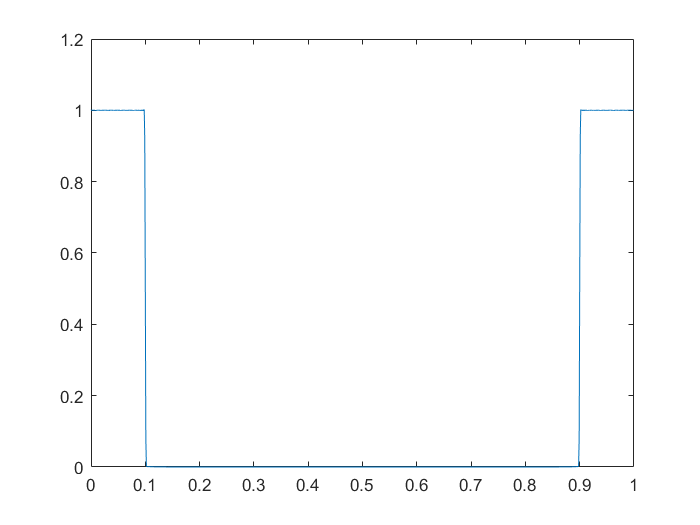

figure
plot(nu, abs(fft(b)))

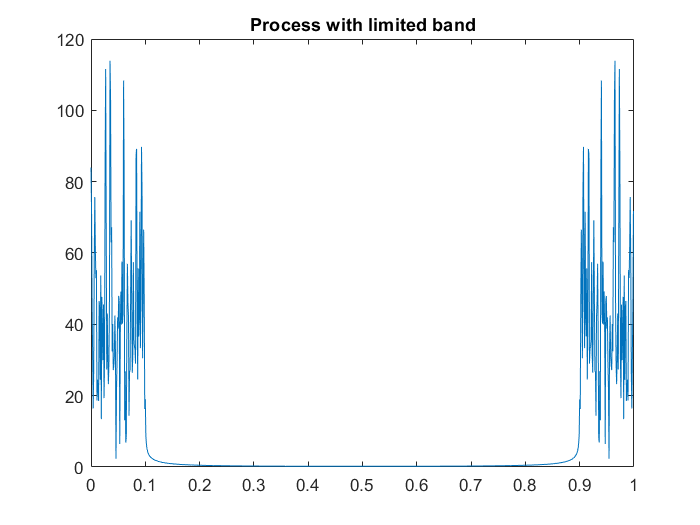

figure
Xv = fft(X);
plot(nu, abs(Xv))
title('Process with limited band')

## 3. Noise Smoothening

Given a filter with impulse response:


$$h_{\left(n\right)} =\left\lbrace \begin{array}{cc}
\frac{1}{8} & ,0\le n\le 7\\
0 & ,n\ge 8
\end{array}\right.$$


**Spectral Density:** The spectral density of the process at the output of the filter will be given by the spectral density $s\left(w\right)$ of an ARMA process.


$$s\left(w\right)=\sigma^2 \left|H\left(\textrm{jw}\right){\left|\right.}^2 =\sigma^2 H\left(\textrm{jw}\right)H^* \left(\textrm{jw}\right)=\sigma^2 \textrm{FTDT}\left\lbrace h\left(n\right)*h\left(-n\right)\right\rbrace \right.$$


Below, we graphically show the convolution $h\left(n\right)*h\left(-n\right)$

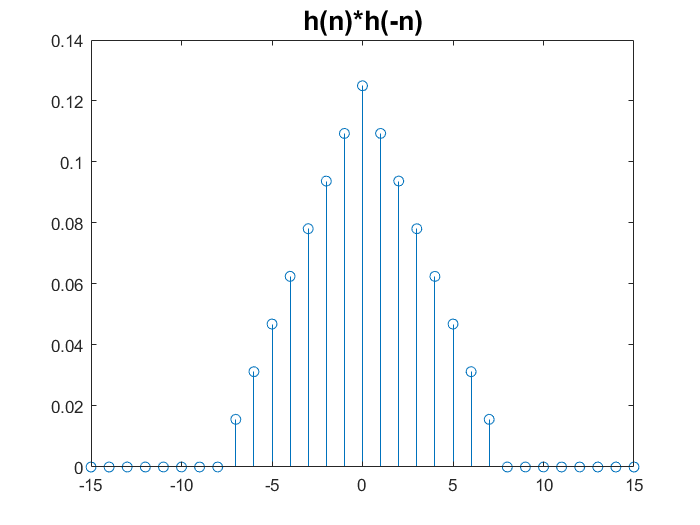

fontsize = 16;

my_h = (1/8) * ones(1,8);
my_h = [ zeros(1,8)  my_h];
my_conv = conv(my_h, flip(my_h));
figure
stem(-15:1:15,my_conv)
title('h(n)*h(-n)', 'fontsize', fontsize)

From the above result, we can write the spectral density by performing the fourier transform in discrete space, where $a=\frac{1}{8}$.


$$s\left(w\right)=\sigma^2 \left\lbrack 8a^2 +2\cdot 7a^2 \cos \left(w\right)+2\cdot 5a^2 \cos \left(2w\right)+2\cdot 5a^2 \cos \left(3w\right)+2\cdot 4a^2 \cos \left(4w\right)+2\cdot 3\cos \left(5w\right)+\dots \right\rbrack$$


**Autocovariance of filter output: **The autocovariance $K_X$ of the filter output is equal to the inverse fourier transform of the spectral density defined previously.


$$K_X \left(n\right)=\sigma^2 h\left(n\right)*h\left(-n\right)$$


Thus, $K_X$ is just the above graph multiplied by $\sigma^2$.

Now, we realize the same results on MATLAB and compare them to the theoretical values.

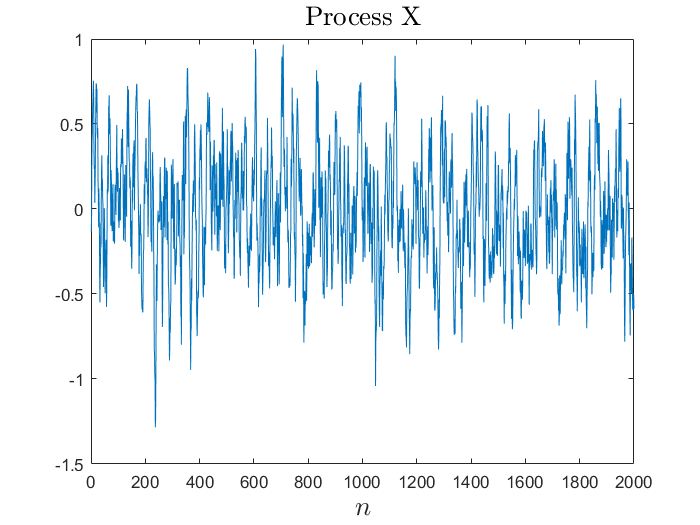

N = 2000;
b = 1/8.*ones(8,1);
a = 1;
P = 1;
e = normrnd(0, 1, N,1);
%e = wgn(N, 1, 20*log10(P));
X=filter(b,a,e);
nu = 0:1/N:1-1/N;

figure
plot(X)
title('Process X','interpreter', 'latex','fontsize',fontsize)
xlabel('$n$', 'interpreter', 'latex','fontsize',fontsize)

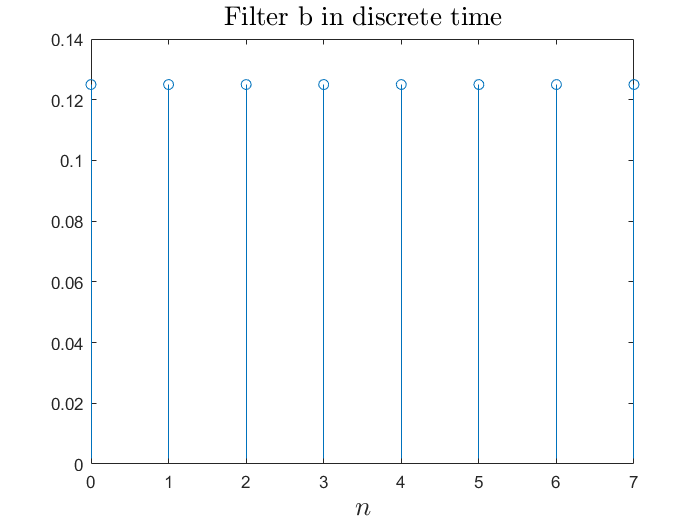

figure
stem(0:1:7,b)
title('Filter b in discrete time','interpreter', 'latex','fontsize',fontsize)
xlabel('$n$', 'interpreter', 'latex','fontsize',fontsize)

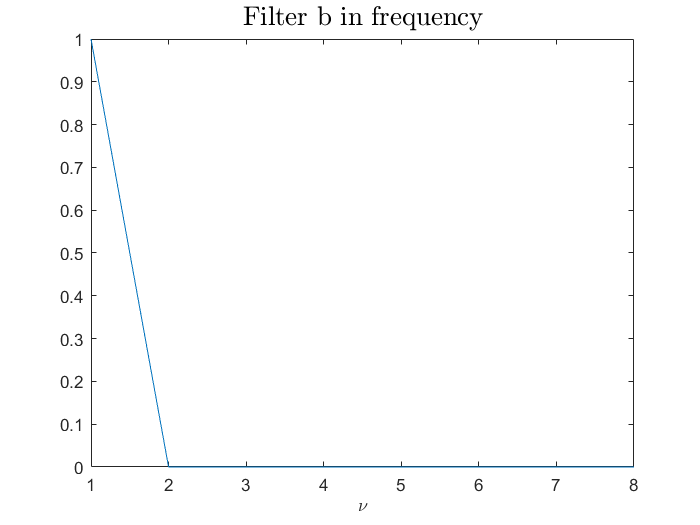

figure
plot( abs(fft(b)))
title('Filter b in frequency','interpreter', 'latex','fontsize',fontsize)
xlabel('$\nu$', 'interpreter', 'latex')

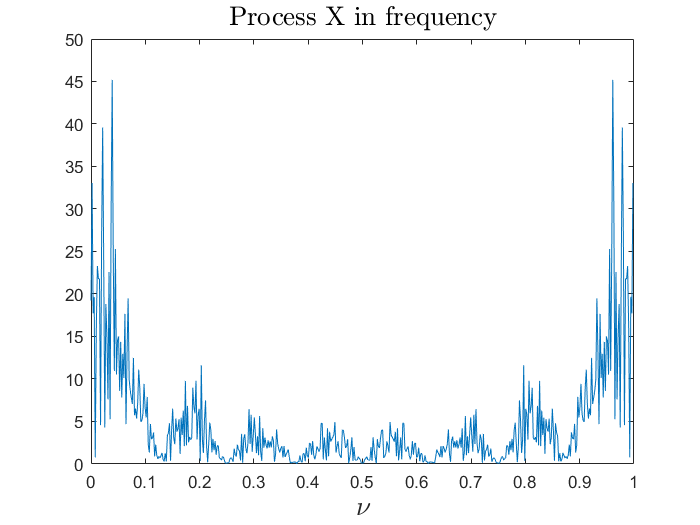

figure
plot(0:1/512:1-1/512, abs(fft(X, 512)))
title('Process X in frequency','interpreter', 'latex','fontsize',fontsize)
xlabel('$\nu$', 'interpreter', 'latex','fontsize',fontsize)

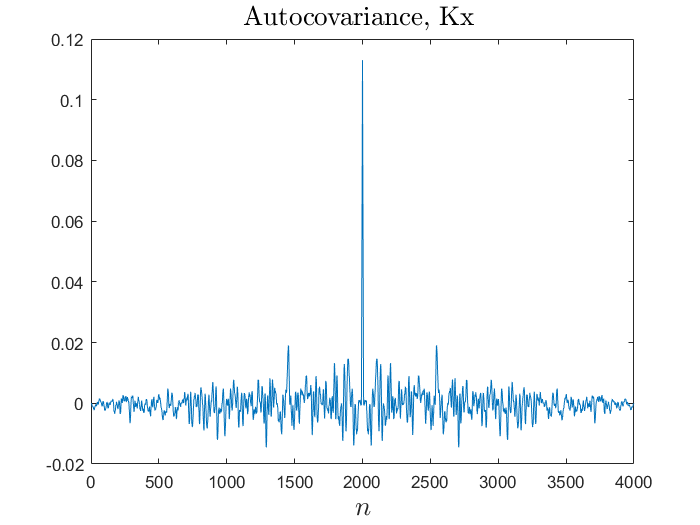

figure
covar = xcov(X);
plot(covar/N)
Kx0 = 20*log10(max(covar));
title('Autocovariance, Kx ','interpreter', 'latex','fontsize',fontsize)
xlabel('$n$', 'interpreter', 'latex','fontsize',fontsize)

Here, we see that the value of $K_X \left(0\right)$, the avearge power of the process is 0.125. This corresponds to the integration performed above, where the power would be $\sigma^2 \;\left\lbrack h\left(n\right)*h\left(-n\right)\right\rbrack \left(0\right)=\sigma^2 \cdot 0\ldotp 125=0\ldotp 125$.

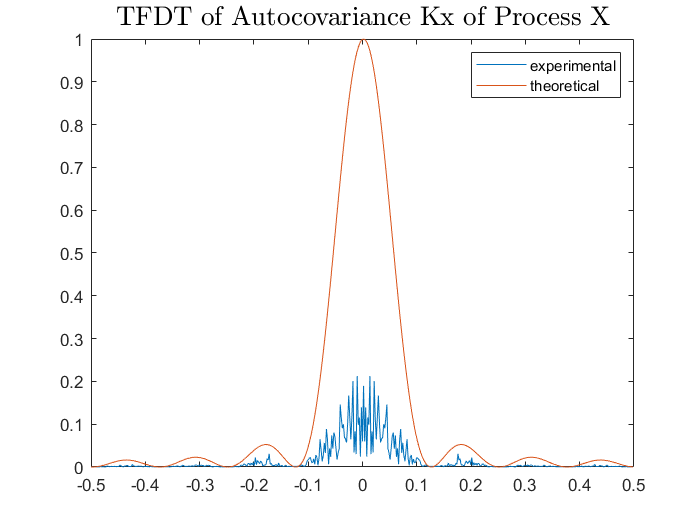

F=-1/2:1/512:1/2-1/512;
TF_Ky = abs(fft(covar/N, 512));
TF_conv = abs(fft(my_conv', 512)); 
figure
plot(F,[TF_Ky(512/2:512); TF_Ky(1:512/2-1)])
%plot(TF_Ky)
hold on
%plot(TF_conv)
plot(F,[TF_conv(512/2:512); TF_conv(1:512/2-1)])
title('TFDT of Autocovariance Kx of Process X','interpreter', 'latex','fontsize',fontsize)
legend('experimental', 'theoretical')

We see that the amplitude of the TFTD of $K_X$ diminished and increases approximately with the same speed as expected from the theoretical result. The modes are also present at the same frequencies. However, at $\nu =0$, we see that the expected amplitude differs largeley from the observed amplitude.

## 4. Autoregressive Process

An Autoregressive Process, AR(2) is associated with the polynomial $A\left(z\right)=1+a_1 z^{-1} +a_2 z^{-2}$ whose poles are complex conjugates. Therefore, we can write the transfer function $H\left(z\right)$ and the poles of the system $p_1$ and $p_2$:


$$H\left(z\right)=\frac{1}{1+a_1 z^{-1} +a_2 z^{-2} }$$



$$\left\lbrace \begin{array}{cc}
a_1 =-\left(p_1 +p_2 \right)=-\left(\rho e^{-\phi } +\rho e^{+\phi } \right)=-2\rho \cos \left(\phi \right) & \\
a_2 =p_1 p_2 =\rho^2  & 
\end{array}\right.$$


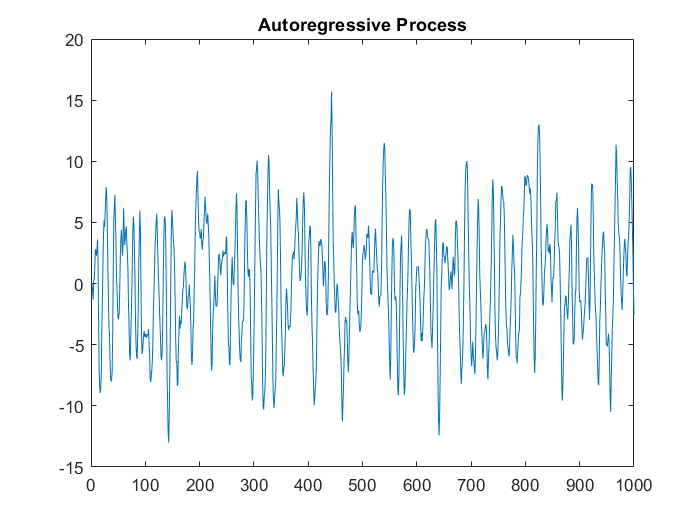

rho = 0.9;
phi = 20;
N = 1000;
a1 = -2*rho*cosd(phi);
a2 = rho^2;
X = zeros(N,1);

for i=3:N
   X(i) = -a1*X(i-1)-a2*X(i-2)+normrnd(0,1);
end

figure
plot(X)
title('Autoregressive Process')

## 5. Sinusoid with noise vs. AR(2) process

We sample the signal $y\left(t\right)=\sin \left(2\pi f_0 t\right)+b\left(t\right)$, where $f_0 =100\;\textrm{Hz}$ and $b\left(t\right)$ is a white gaussian noise of variance $\sigma^2 =0\ldotp 04$, with $N$ points at the sampling frequency $f_s =1000\;\textrm{Hz}$. The result is shown below.

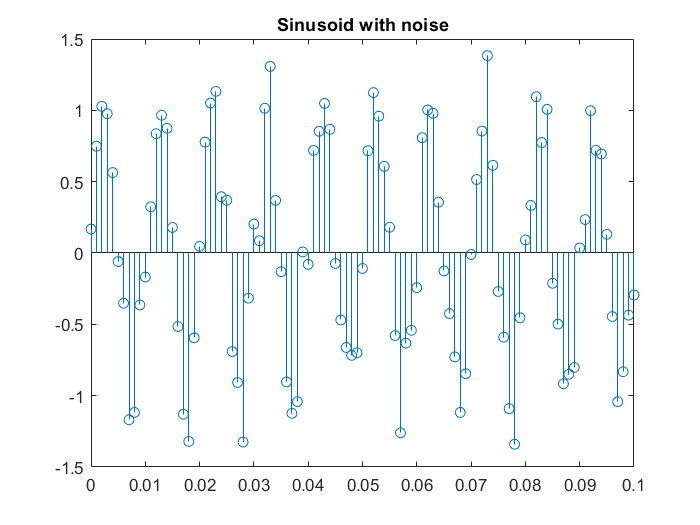

N = 100;
fe = 1000;
fo = 100;
var = 0.04;
numCycl = N*fo/fe;
t = 0:1/fe:numCycl*1/fo;
y = zeros(N, 1);
for i=1:N+1
    y(i) = sin(2*pi*fo*t(i)) + normrnd(0, sqrt(var));
end

figure
stem(t, y)
title('Sinusoid with noise')

To comapre the above with a AR(2) process, we have 


$$x\left(n\right)+a_1 x\left(n-1\right)+a_2 x\left(n-2\right)=\epsilon \left(n\right)$$


where $\epsilon \left(n\right)$is a white gaussian noise of variance $\sigma^2$. The resonant frequency associated with $x\left(n\right)$ is 100 Hz. We want to find the value of $\sigma^2$ for which the AR(2) process $x$ and the sinusoid with noise $y$ have the same average power.

We can show that $\left|a_1 \right|<1$ and $\left|a_2 \right|<1$, assuming that the poles of the transfer function are complex conjugates and the the filter is causal and stable. The filter has a maximum gain the the frequency $\nu_r$:


$$\nu_r =\frac{1}{2\pi }\mathrm{arccos}\left(-\frac{a_1 \left(1+a_2 \right)}{4a_2 }\right)$$


We know that the average power of $x$ is equal to the autocorrelation function $r_x \left(0\right)$since $x$ is centered at 0. The [Yule-Walker equations](https://en.wikipedia.org/wiki/Autoregressive_model#Yule–Walker_equations) tell us:


$$r_x \left(k\right)=-\sum_{i=1}^2 a_i r_x \left(k-i\right)+\sigma^2 \sum_{j=0}^0 b_j \bar{h\left(j-k\right)}$$


Using $r_x \left(2\right)$ to replace in $r_x \left(0\right)$, we get the value for $r_x \left(1\right)$. Equating this with the value of $r_x \left(1\right)$ from the Yule Walker equation we finally get:


$$\sigma^2 =r_x \left(0\right)\left\lbrack 1-\frac{a_1^2 }{{\left(1+a_2 \right)}^2 }\right\rbrack \left(1-a_2^2 \right)$$


where $r_x \left(0\right)=P_{{\mathrm{av}}_y } =1+\sigma_b^2 =\frac{1}{2}+0\ldotp 04$. With the above equation and the one for $\nu_r$, we have a system of 2 equations and 3 unknowns. We choose $a_2 =0\ldotp 83$, giving $\sigma^2 =0\ldotp 0599$. We show the results below:

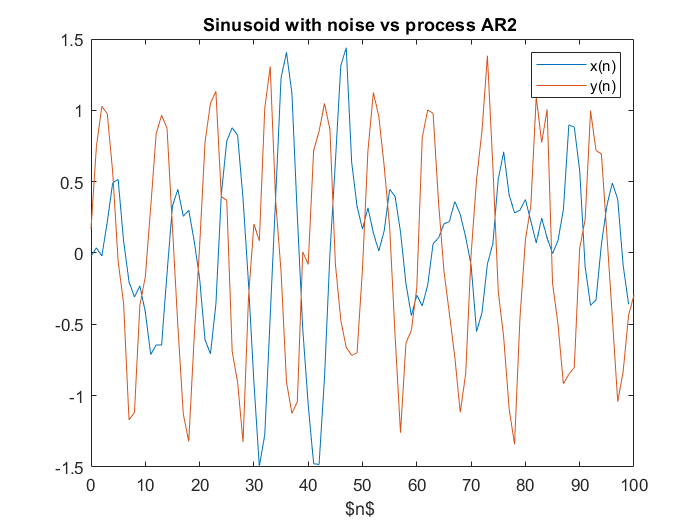

a2 = 0.83; % tout valeur 0<a2<1 marche
a1 = -4*a2*cos(2*pi*fo/fe)/(1+a2);
nu_r = acos(-a1*(1+a2)/(4*a2))/(2*pi);
Pav = 1/2+ var;
sigma_carr = 1/2+var;
N = 100;
x = zeros(N, 1);
sigma_carr_x = Pav *(1 -( a1 ^2) /(1+ a2) ^2) *(1 - a2 ^2);
x (1) = normrnd (0, sqrt ( sigma_carr_x ));
x (2) = -a1*x (1) + normrnd (0, sqrt ( sigma_carr_x ));
for i=3:N
    x(i) = -a1*x(i-1)-a2*x(i-2)+normrnd(0,sqrt(sigma_carr_x));
end

figure
plot (0:N -1,x)
title ('Sinusoid with noise vs process AR2 ')
hold on
plot (0:N, y)
legend ('x(n)','y(n)')
xlabel ('$n$ ')

We see that the two processes are similar in terms of amplitude and frequency. The differences come becuase of the noise component. This becomes more visible in the frequency domain:

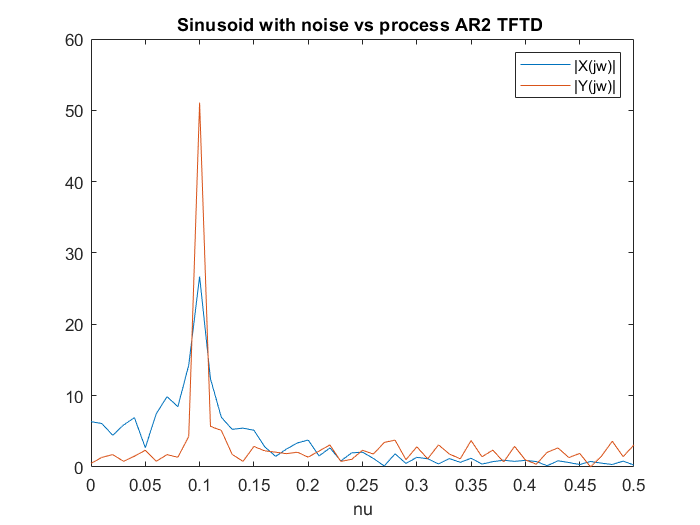

FT_x = abs( fft (x));
FT_y = abs( fft (y));
v = 0:1/( floor (N)) :0.5;
figure
plot (v, FT_x (1:N /2+1) );
title ('Sinusoid with noise vs process AR2 TFTD ')
hold on
plot (v, FT_y (1:N /2+1) )
legend ('|X(jw)|','|Y(jw)|')
xlabel ('nu')